clc
clear

% Initial value - No acceleration
X1=1;                       % For iter func 1
X2=1;                       % For iter func 2
X3=1;                       % For iter func 3

% Initial value - Steffensen acceleration
X1s=1;                      % For iter func 1
X2s=1;                      % For iter func 2
X3s=1;                      % For iter func 3

% Initial value - Newton iteration
X4=1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Direct functions
% Func 1 and func 2 had vibrations, 
% while func 3 is converged.
% You may check the result in xi_arr (i=1,2,3) from the workspace.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fprintf("Direct functions:\n");

Direct functions:


[X1,step1,x1_arr]=directIter(@cube,@noConv1,X1,1E-7,100);

Not converged ! Iteration: 100


[X2,step2,x2_arr]=directIter(@cube,@noConv2,X2,1E-7,100);

Not converged ! Iteration: 100


[X3,step3,x3_arr]=directIter(@cube,@conv,X3);

Converged! Iteration: 23


fprintf("\n");

%%%%%%%%%%%%%%%%%%%%%%%%%
% Steffensen acceleration
% You may check the result in xis_arr (i=1,2,3) from the workspace.
%%%%%%%%%%%%%%%%%%%%%%%%%
fprintf("Steffensen acceleration:\n");

Steffensen acceleration:


[X1s,step4,x1s_arr]=steffen_acc(@cube,@noConv1,X1s);

Converged! Iteration: 4


[X2s,step5,x2s_arr]=steffen_acc(@cube,@noConv2,X2s);

Converged! Iteration: 7


[X3s,step6,x3s_arr]=steffen_acc(@cube,@conv,X3s);

Converged! Iteration: 3


fprintf("\n");

%%%%%%%%%%%%%%%%%%
% Newton iteration
% You may check the result in x4_arr from the workspace.
%%%%%%%%%%%%%%%%%%
fprintf("Newton iteration:\n");

Newton iteration:


[X4,step7,x4_arr]=newton(@cube,X4);

Converged! Iteration: 4


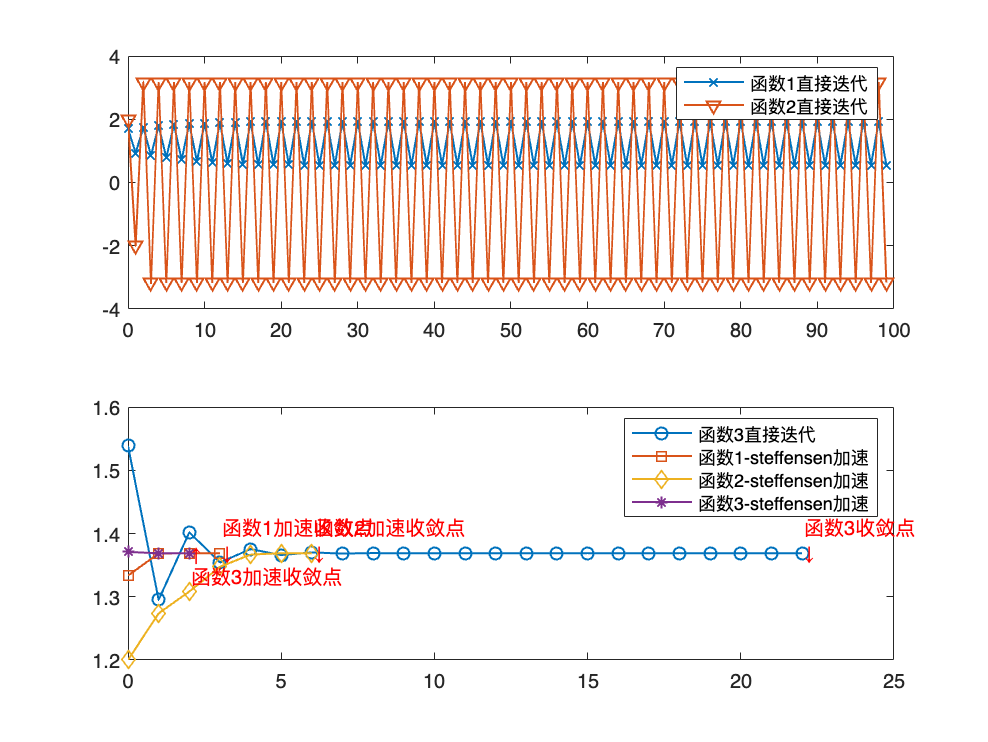

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
% 1. Visualize the process of iteration, pay attention to 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(2,1,1);
plot(0:step1-1,x1_arr,"-x",'LineWidth',1);hold on;
plot(0:step2-1,x2_arr,"-v",'LineWidth',1);
legend('函数1直接迭代',...
       '函数2直接迭代');
subplot(2,1,2);
plot(0:step3-1,x3_arr,"-o",'LineWidth',1);hold on;
plot(0:step4-1,x1s_arr,"-square",'LineWidth',1);hold on;
plot(0:step5-1,x2s_arr,"-diamond",'LineWidth',1);hold on;
plot(0:step6-1,x3s_arr,"-*",'LineWidth',1);

% Mark the converged points
text(step3-1,X3+0.02,{'函数3收敛点','\downarrow'},'Color','red');
text(step4-1,X1s+0.02,{'函数1加速收敛点','\downarrow'},'Color','red');
text(step5-1,X2s+0.02,{'函数2加速收敛点','\downarrow'},'Color','red');
text(step6-1,X3s-0.02,{'\uparrow','函数3加速收敛点'},'Color','red');

% Legend
legend('函数3直接迭代', ...
       '函数1-steffensen加速', ...
       '函数2-steffensen加速', ...
       '函数3-steffensen加速');

function y=cube(x)          % Function to be solved
y=x.^3+2.*x.^2+10.*x-20;
end

function y=noConv1(x)       % Iter func 1, not converged
y=(20-2.*(x.^2)-x.^3)./10;
end

function y=noConv2(x)       % Iter func 2, not converged
y0=20-10*x-2*x^2;
if sign(y0)==-1
    y=-power(abs(y0),1/3);
else
    y=power(y0,1/3);
end
end

function y=conv(x)          % Iter func 3, converged but slow
y=20/(x^2+2*x+10);
end